# Compare Density and Rate models

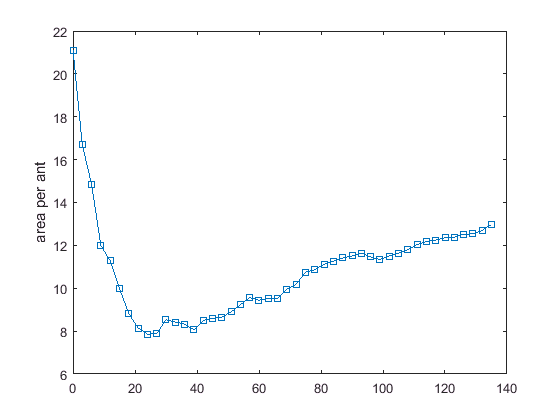

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')
t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
A = M(11).Mean(t0:tend);
Aer = M(11).SEM(t0:tend);
N = M(13).Mean(t0:tend);
Ner = M(13).SEM(t0:tend);

% rates
dAdt = diff(A)./3;
dNdt = diff(N)./3;

% choose ast
a = A./N;
figure; plot(t1,a,'-s')
ylabel('area per ant')

Mean_aST = mean(a(end-10:end)) % mean of last month

Mean_aST = 12.3059

choose ast = 12.3 for mean data

## Find 'r' , optimal rate parameter for density model

dA1_func = @(A,N,ast,r) N.*r.*(1-(A./N)./ast);
R = 0.5:0.001:1.5;
RMSE_dA = zeros(numel(R)-1,1);
RMSE_A = zeros(numel(R),1);

for j=1:numel(R)
    Am1 = zeros(numel(A),1);
    dA1 = zeros(numel(A)-1,1);
    Am1(1)=A(1);
    for i=2:numel(A)
        dA1(i-1) = dA1_func(A(i-1),N(i-1),12.3,R(j));
        if dA1(i-1)<0
            dA1(i-1)=0;
        end
        Am1(i) = Am1(i-1)+3.*dA1(i-1);
    end
    RMSE_dA(j) = sqrt(immse(dAdt,dA1));
    RMSE_A(j) = sqrt(immse(A,Am1));
end

[Min,I] = min(RMSE_dA)

Min = 0.6417

I = 335

disp('optimal r value dAdt')

optimal r value dAdt


R(I)

ans = 0.8340

[Min,I] = min(RMSE_A)

Min = 8.7897

I = 400

disp('optimal r value A')

optimal r value A


R(I)

ans = 0.8990

## Compare models on mean data

% density model
AST = 12.3;
Rr = 0.899;
Am1 = zeros(numel(A),1);
dA1 = zeros(numel(A)-1,1);
Am1(1)=A(1);
for i=2:numel(A)
    dA1(i-1) = dA1_func(A(i-1),N(i-1),AST,Rr);
    if dA1(i-1)<0
       dA1(i-1)=0;
    end
    Am1(i) = Am1(i-1)+3.*dA1(i-1);
end
% Rate model
[dA2,Am2] = dAdtModel2(-51,0,2.175,0,dNdt,A(1));


figure
subplot(1,2,1)
plot(t1(1:end-1),dAdt,'-s',t1(1:end-1),dA1,t1(1:end-1),dA2,'LineWidth',2)
xlabel('time [days]')
ylabel('digging rate [cm^2/day]')
legend({'Mean Total Area','Density model','Rate model'},'Location','northwest')
RMSE1 = sqrt(immse(dAdt,dA1))

RMSE1 = 0.6459

RMSE2 = sqrt(immse(dAdt,dA2))

RMSE2 = 0.4987



f = subplot(1,2,2)

f =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3326 0.8150]
            Units: 'normalized'

  Show all properties


c = colormap(lines);

set(f,'defaultAxesColorOrder',[c(1,:);0 0 0]);
    yyaxis right
    plot(t1,N,'--k','LineWidth',2)
    ylabel('no. ants')
    hold on
    yyaxis left
%plot(t1,A,'-s',t1,Am1,t1,Am2)
    plot(t1,A,'-s','Color',c(1,:),'LineWidth',2)
    plot(t1,Am1,'-','Color',c(2,:),'LineWidth',2)
    plot(t1,Am2,'-','Color',c(3,:),'LineWidth',2)
xlabel('time [days]')
ylabel('area [cm^2]')
RMSE1 = sqrt(immse(A,Am1))

RMSE1 = 8.7897

RMSE2 = sqrt(immse(A,Am2))

RMSE2 = 2.9354

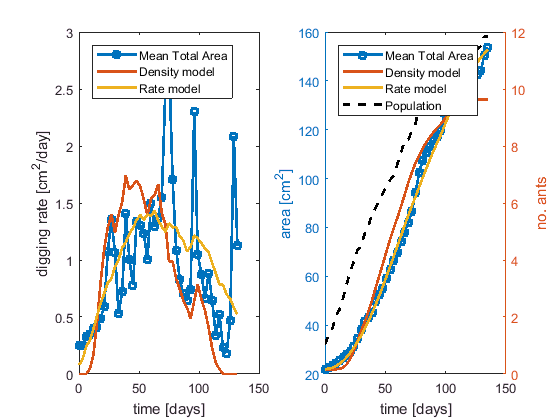


legend({'Mean Total Area','Density model','Rate model','Population',},'Location','northwest')

## Check for 3 experiments: F3, F4 and F25

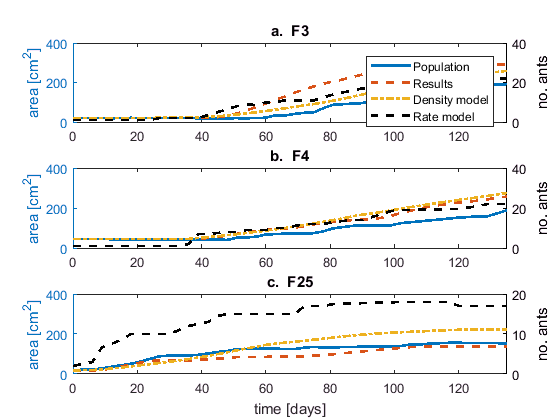

   90.9282


   31.3276


   41.7882


   52.0867


   25.5761


   44.4041


fig = figure;

set(fig,'defaultAxesColorOrder',[c(1,:);0 0 0]);
j=0;
letter = {'a','b','c'};
for k=[3 4 25]
    j=j+1;
    A_n = S(k).B{t0:tend,11};
    N_n = S(k).B{t0:tend,13};
    % rates
    dAdt = diff(A_n)./3;
    dNdt = diff(N_n)./3;
    
    % density model
    Am1 = zeros(numel(A_n),1);
    Am1(1)=A_n(1);
    for i=2:numel(A_n)
        dA1 = dA1_func(A_n(i-1),N_n(i-1),8.5,Rr);
        if dA1<0
            dA1=0;
        end
        Am1(i) = Am1(i-1)+3.*dA1;
    end
    % Rate model
    [MdAdt2,Am2] = dAdtModel2(-51,0,2.175,0,dNdt,A_n(1));
    
    subplot(3,1,j)
    % plot  pop curve
    yyaxis right
    plot(t1,N_n,'--k','LineWidth',2)
    ylabel('no. ants')
    hold on
    yyaxis left
    plot(t1,A_n,'LineStyle','-','Color',c(1,:),'LineWidth',2)
    plot(t1,Am1,'LineStyle','--','Color',c(2,:),'LineWidth',2)
    plot(t1,Am2,'LineStyle','-.','Color',c(3,:),'LineWidth',2)
    xlim([0 135])
    if j==1
        legend({'Results','Density model','Rate model','Population'})
    elseif j==3
        xlabel('time [days]')
    end
    ylabel('area [cm^2]')
    
    titles = strcat(letter(j),'.  F',num2str(k));
    title(titles)
  
    RMSE1 = sqrt(immse(A_n,Am1));
    disp(RMSE1)
    RMSE2 = sqrt(immse(A_n,Am2));
    disp(RMSE2)
end